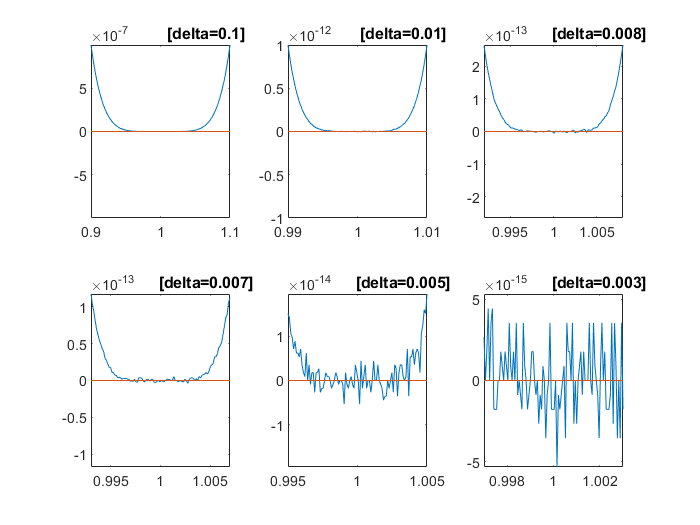

% ROUNDEX: Illustration of subtractive cancellation and
% roundoff error in a Taylor polynomial approximation.
%
% A set of six plots (x-1)^6 near x=1 with a successively 
% refined scale.  The function can also be evaluated in 
% expanded form as 
% x^6 - 6x^5 + 15x^4 - 20x^3 + 15x^2 - 6x + 1.
%
% Taken from "Introduction to Scientific 
% Computing, 2nd ed.", by C. F. van Loan.
%
% See also: 
%    www.mathworks.com/company/newsletter/pdf/Fall96Cleve.pdf
%
% AUTHOR: John Stockie <stockie@math.sfu.ca>
% DATE:   Dec 27, 2019
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Set 'whichplot' to 0 or 1 to select a function:
whichplot = 0; % 0=expanded, 1=factored

clf
close all
k = 0;   % number of delta-plots
n = 100; % number of plotting points

for delta = [.1 .01 .008 .007 .005 .003]

  x = linspace( 1-delta, 1+delta, n )';

  if( whichplot == 0 ) 
    y = x.^6 -  6*x.^5 + 15*x.^4 - 20*x.^3 ...
	+ 15*x.^2 - 6.*x + ones(n,1);
  else
    y = (x - 1).^6;
  end
  
  k = k + 1;
  subplot( 2, 3, k )
  plot( x, y, x, zeros(1,n) )
  title( ['                     ', ...
	  '[delta=', num2str(delta),']'], ...
	 'fontweight', 'bold', 'fontsize', 12 );
  axis( [ 1-delta 1+delta -max(abs(y)) max(abs(y)) ] )
end

% Write plot to a JPEG file.
if( whichplot == 0 )
  print -djpeg roundex1
else
  print -djpeg roundex2
end


subplot(111);  % reset plotting window